# **Numerical simulation of a COVID-19 SIR model**

**Student Name: Boxuan Zhang**

**Student ID: 95535906**

*I hereby confirm that the present report is my own work. If any texts or codes from books, papers,  the Web, or any other sources have been copied or in any other way used, all references have been  acknowledged and cited. I am aware that the instructor has the authority to report and investigate any potential academic misconduct in this course, and such misconduct could lead to failing this  course. If I have employed any AI models (including but not limited to ChatGPT), I have appropriately and explicitly acknowledged their use in the report whenever the results were generated with the aid of AI.*

## Task 2

1)

A mathmatical model is to convert problems in real life into math problems, then use function or calculation to find the best solution for the math questions and apply the solution into the real word. When we use mathmatical modeling, we first analyze the problem we have, then we use math like function, algebra to build a model, and we try to solve the model by calculation. When we get a solution, we apply it into real life to test the model, and we will optimize the model and parameter to find the best solution. Mathmatical model include many knowledge like calculus, linear algebra and discrete math. A good mathmatical model enable people to preidct the future trend, like the socket in the fincial market and medical experiment. Mathmatical modeling is essential to our life, we can see it in everywhere like the interest rate calculation, amazon delivery evaluation and temperature prediction. Mathmatical modeling build a solid base for our life.

2)

SIR model is a kind of mathmatical model which used to predict the number of people who got COVID-19 in the future. SIR model mainly constitute by three parts, the number of susceptible people, number of infectious people and number of recovered people. SIR model preidct the number of infectious poeple by calculating the rate of those three parts

3)


$$\frac{\textrm{dS}}{\textrm{dt}}=-\beta \frac{I}{N}S$$



$$\frac{\textrm{dI}}{\textrm{dt}}=\beta \frac{I}{N}S\;-\gamma I\;$$



$$\frac{\textrm{dR}}{\textrm{dt}}=\gamma I$$


$\beta$：the probability of being infected by infectious

$N$: the population size

$I$: the population of infectious

$S$: the population of susceptible people

$\gamma$: the probability of people be recovered

4)

    4.1)  $\beta \frac{I}{N}S$ means the rate of people get the COVID-19 every day. It is negative since when people get COVID-19, they will not in the group of susceptible, so the number of people in the susceptible group will decrease everyday.

    4.2)  With the only one term because the recovery people only come from the infectious people. $\gamma I$ means the number of people become recoverd every day.

    4.3)  We can use the aussmption in the circumanstance that there is no baby born and there is no person who is natural death, whcih means the total population is closed or not changed.

    4.4)  $\frac{\beta }{\gamma }$ means the rate between probability of infectious and probability of recovery, when the rate is greater than 1 means the probability of infectious is greater than probability of recovery, which means that the disease begin spreading in the population.

    4.5) In the begining of 2020, the people in Wuhan, China appear large-scale infectious of COVID-19, $R_0$ increased to 4, which means that number of infectious people increase hugely everyday.

## Task 3

1) 

N = 10000; % total population
R0 = 10; % initial recovery
I0 = 200; % initial infectious
S0 = N - R0 - I0; % initial susceptible
y0 = [S0; I0; R0];

beta = 0.75; % infecious probability
gamma = 0.15; % recovery probability

time = [0:45];

% 2)
[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
S = y(:,1); % susceptible rate
I = y(:,2); % infectious rate
R = y(:,3); % recovery rate

3)

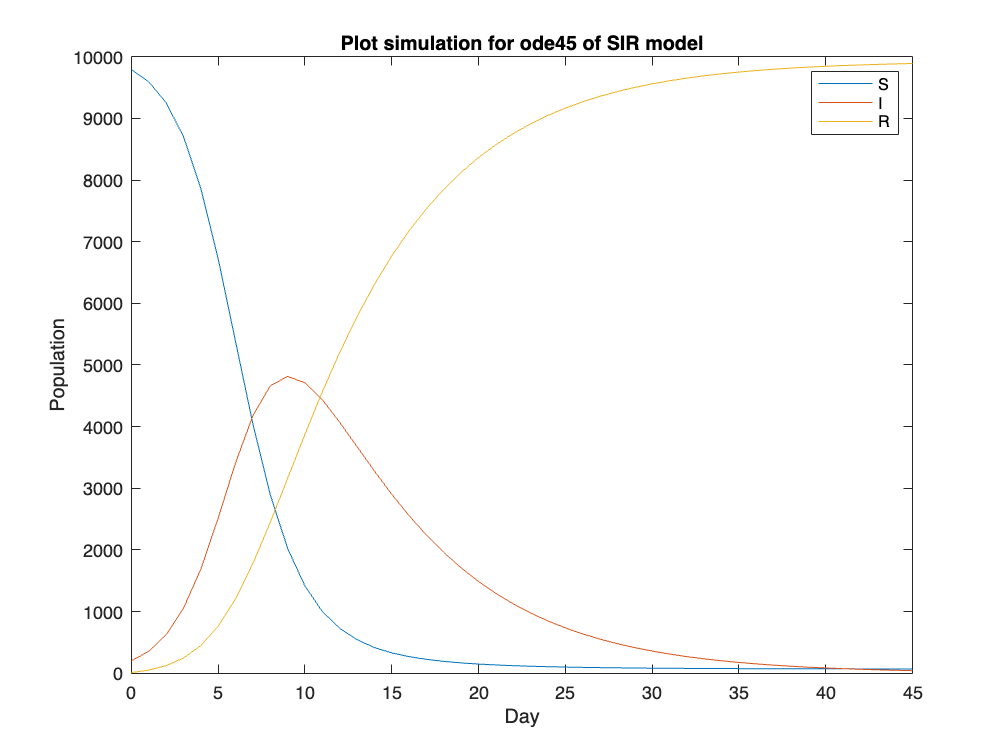

% Simulation
plot(time, S)
hold on 
plot(time, I)
plot(time, R)
% 4)
title("Plot simulation for ode45 of SIR model")
xlabel("Day")
ylabel("Population")
legend('S', 'I', 'R')
hold off

5)

**From the plot, the blue line is population of susceptible, red line is population of infectious and yellow line is population of recovery. From 0 to 10 days, the population of susxepitble is decreasing and infectious is increasing, which means the outbreak begins. From 10 to 20 days, the susceptible decrease and infectious increase and reach the peak, but the recvoery begin increasing. From 20 to 45 days, the infectious decreases and recovery increases, which means most people are already recovered from the outbreak.**

6)

**The reproduction is **$R_0$**, which is the rate between probability of infectious and probability of recovery, the **$R_0 =\frac{\beta }{\gamma }=\frac{0\ldotp 1}{0\ldotp 15}\approx 0\ldotp 667$

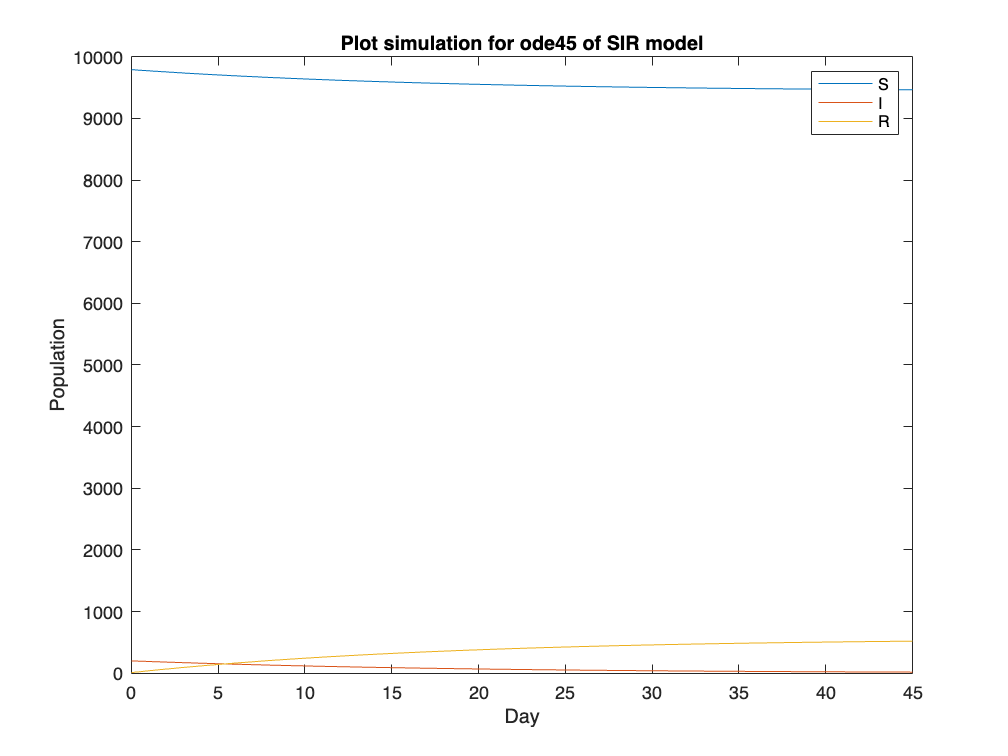

beta = 0.1; % infectious probability
gamma = 0.15; % recovery probabiity

time = [0:45];

[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
S = y(:,1); % dS
I = y(:,2); % dI
R = y(:,3); % dR

% Simulation
plot(time, S)
hold on 
plot(time, I)
plot(time, R)
title("Plot simulation for ode45 of SIR model")
xlabel("Day")
ylabel("Population")
legend('S', 'I', 'R')
hold off

**From the simulation with **$\beta =0\ldotp 1$**, we can see that the population of susceptible is change few during 45 days, which means there is no outbreak during 45 days.**

7)

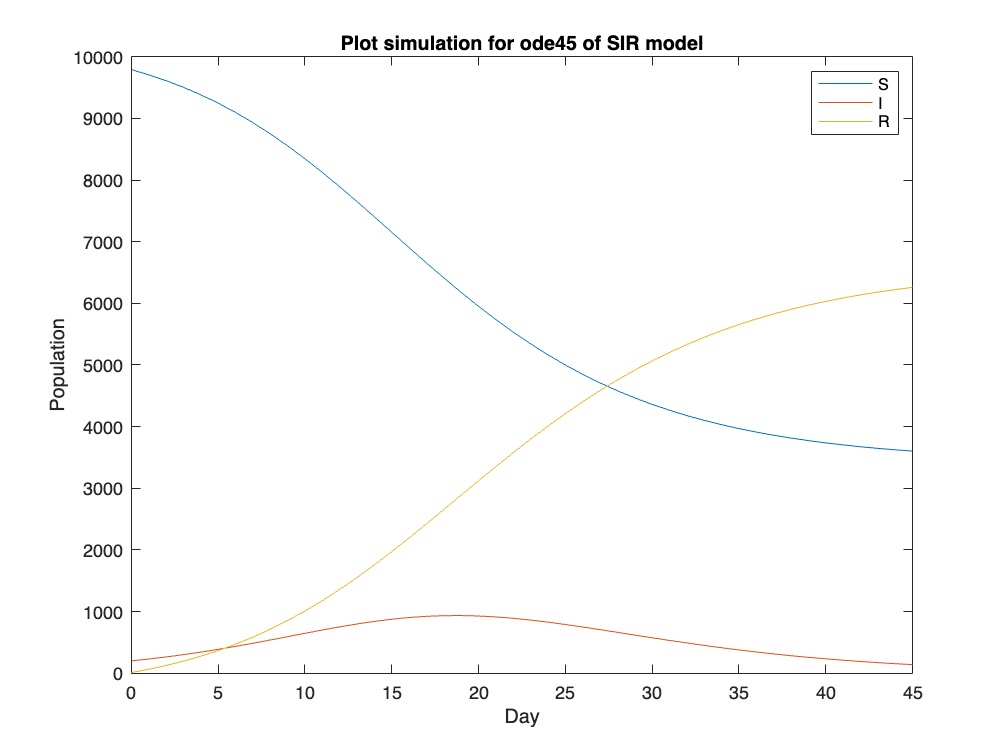

beta = 0.4; % infectious probability
gamma = 0.25; % recovery probability

[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
S = y(:,1); % dS
I = y(:,2); % dI
R = y(:,3); % dR

% Simulation
plot(t, S)
hold on 
plot(t, I)
plot(t, R)
title("Plot simulation for ode45 of SIR model")
xlabel("Day")
ylabel("Population")
legend('S', 'I', 'R')
hold off

**From the simulation with **$\beta =0\ldotp 4$** and **$\gamma =0\ldotp 25$**, we can see that the population of susceptible is decreasing slowly and population of infectious is increasing slowly. Also note the population of recovery, the rate of recovery is faster than the rate of infectious. Thus we can conclude that with the better midecation, the outbreak may begins but it can not cause plenty of infectious.**

## Task 4

2)

N = 10000;
R0 = 10;
I0 = 200;
S0 = N - R0 - I0;
y0 = [S0; I0; R0];

time = [0:45];

[t, y] = ode45(@(t,y) simple_SIR_2(t, y), time, y0);
S = y(:,1);
I = y(:,2);
R = y(:,3);

3）

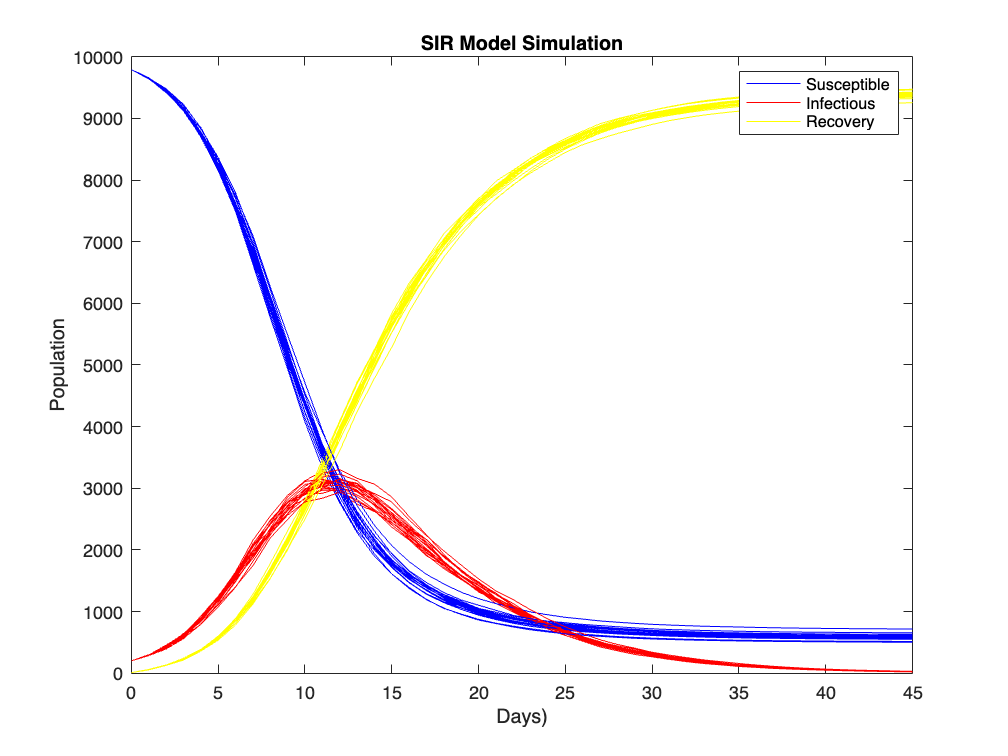

% random 20 times simulation
for i = 1:20
    [t, y] = ode45(@(t,y) simple_SIR_2(t, y), time, y0);

    plot(t, y(:,1), 'b');
    hold on;
    plot(t, y(:,2), 'r');
    plot(t, y(:,3), 'y');
end

title('SIR Model Simulation');
xlabel('Days)');
ylabel('Population');
legend('Susceptible', 'Infectious', 'Recovery');
hold off;

**From the plot, in 20 times run, most the infectious group (red lines) will reach the peak during 5 to 15 day, the susceptible group will decrease from 0 to 45 day, after the 25th day, the population of susceptible decrease slowly, which means less people are infected. The recovery group (yellow lines) increase from 0 to 45 day, after the 35th day, the population of recovery is increase slowly, which means less people are recovered from the disesase. In conclusion, from 20 times running, the outbreak will reach the peak during 5 to 15day, and it will begin decreasing effects after 20 days.**

## Task 5

1)

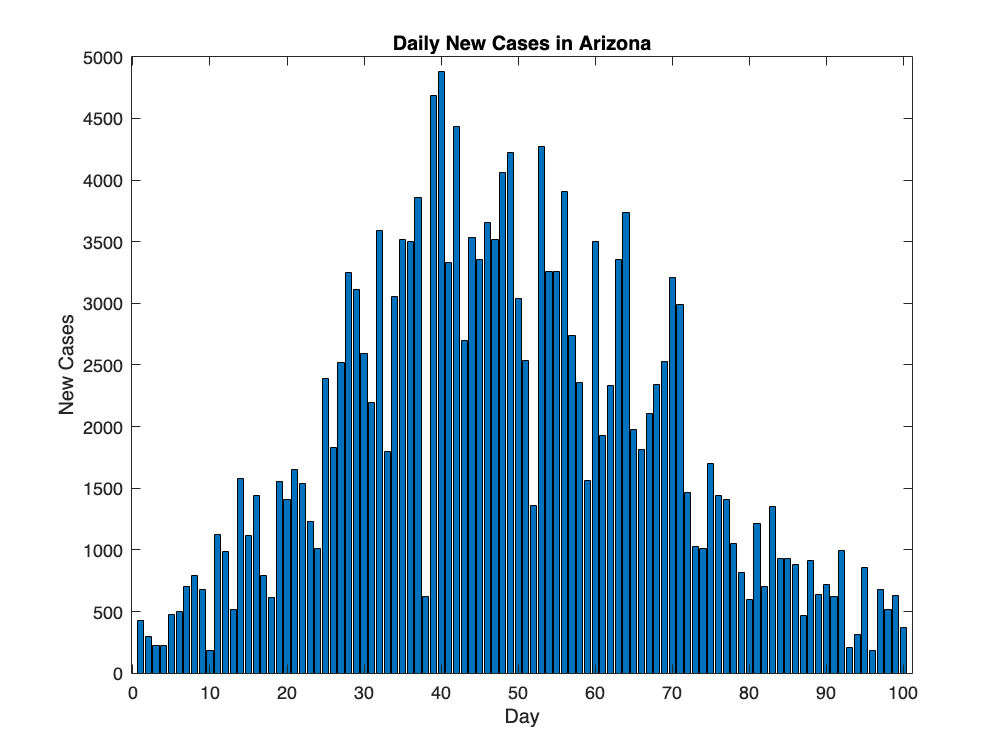

load("ArizonaData.mat") % import Data
daily_new_case = ArizonaData(:,1); % number of infectious
day = 1:length(daily_new_case); % time
bar(day, daily_new_case);
xlabel("Day")
ylabel("New Cases")
title("Daily New Cases in Arizona")

2)

% First day new cases
x = daily_new_case(1);

3)

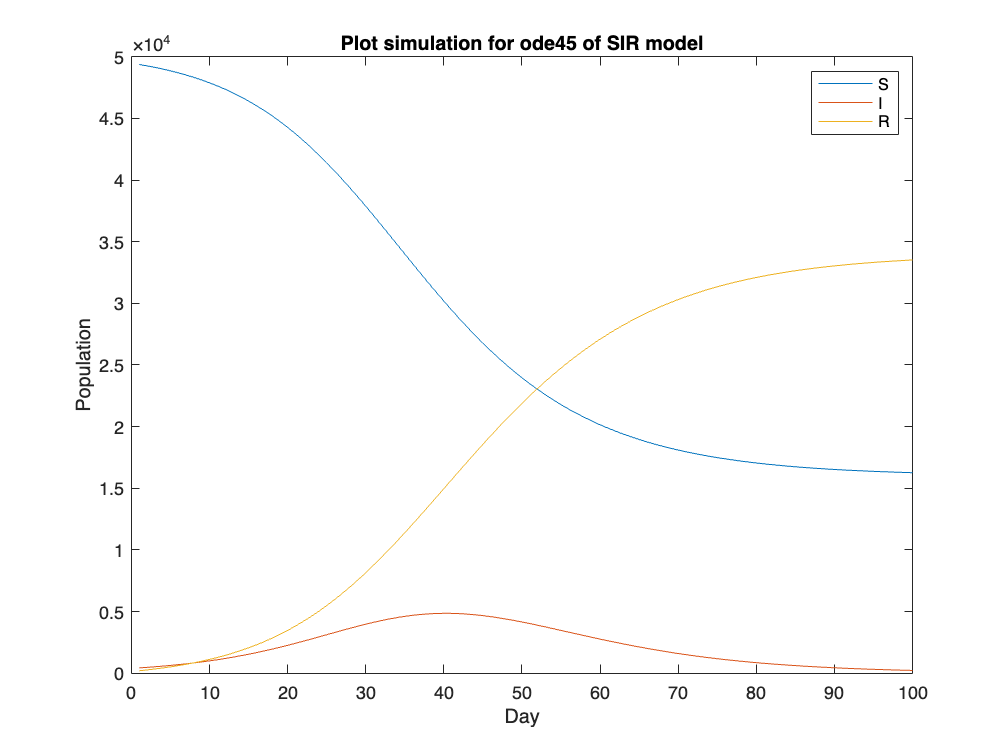

N = 50000;
R0 = 200; % initial recovery
I0 = x; % initial infectious 
S0 = N - R0 - I0; % initial susceptible 
y0 = [S0; I0; R0];

beta = 0.25; % rate of infectious
gamma = 0.15; % rate of recovery

time = day; % 100 days

[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
S = y(:,1);
I = y(:,2);
R = y(:,3);
plot(time, S)
hold on 
plot(time, I)
plot(time, R)
title("Plot simulation for ode45 of SIR model")
xlabel("Day")
ylabel("Population")
legend('S', 'I', 'R')
hold off

4)

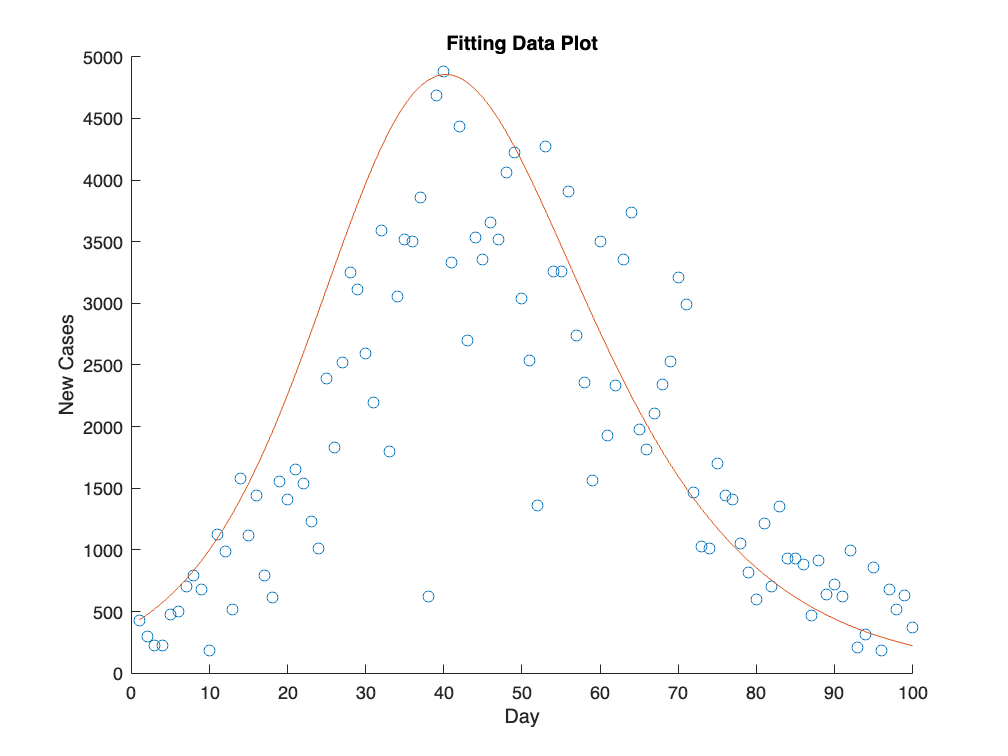

scatter(day, daily_new_case);
hold on;
plot(time, I)
xlabel("Day")
ylabel("New Cases")
title("Fitting Data Plot")
hold off;

**Discuss: In first 40 days, the model overestimate the daily new cases, we can see the infectious value is higher than real value. After 40 days, the model underestimate the daily new cases, we can see that the infecious value is lower than the real value.**

5)

% fitting error between infectious rate and daily new cases
fitting_err = [];
for i = 1:length(daily_new_case)
    err = abs(I(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 6.8321e+04

6)

    (1)

% fitting error 1
beta = 0.25;
gamma = 0.13;
[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
I = y(:,2);
fitting_err = [];
for i = 1:length(daily_new_case)
    err = abs(I(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 1.3480e+05

   (2)

% fitting error 2
beta = 0.24;
gamma = 0.15;
[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
I = y(:,2);
fitting_err = [];
for i = 1:length(daily_new_case)
    err = abs(I(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 5.1635e+04

    (3)

% fitting error 3
beta = 0.24;
gamma = 0.13;
[t, y] = ode45(@(t,y) simple_SIR(beta, gamma, t, y), time, y0);
I = y(:,2);
fitting_err = [];
for i = 1:length(daily_new_case)
    err = abs(I(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 1.1454e+05

## Task 6

1)

daily_new_case = ArizonaData(:,1); % number of daily new cases
daily_death = ArizonaData(:,2); % number of dialy death
time = 1:length(daily_new_case);
N = 50000;
I0 = daily_new_case(1); % initial infectious
R0 = 200; % initial recovery
D0 = daily_death(1); % initial death
S0 = N - I0 - R0 -D0; % initial susceptible
y0 = [S0, I0, R0, D0];
beta = 0.22; % infectious probability
gamma = 0.12; % recovery prbability
delta = 0.016; % death probability

2)

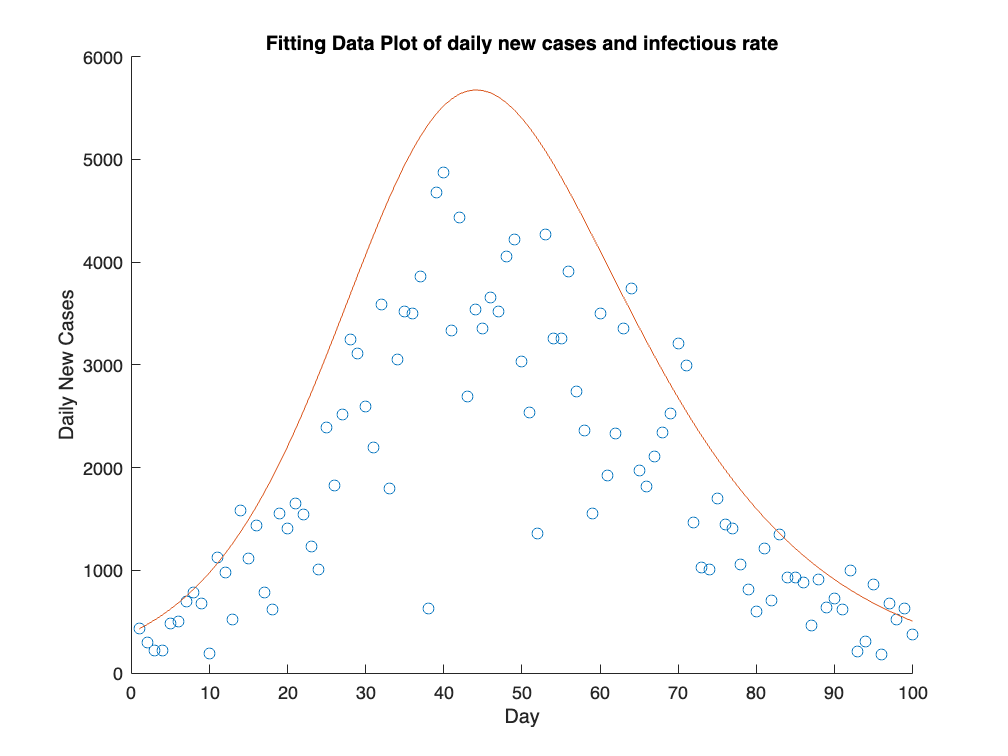

[t,y] = ode45(@(t, y) simple_SIRD(beta, gamma, delta, t, y), time, y0);
scatter(time, daily_new_case)
hold on;
plot(time, y(:,2))
xlabel('Day')
ylabel('Daily New Cases')
title('Fitting Data Plot of daily new cases and infectious rate')
hold off;

3)

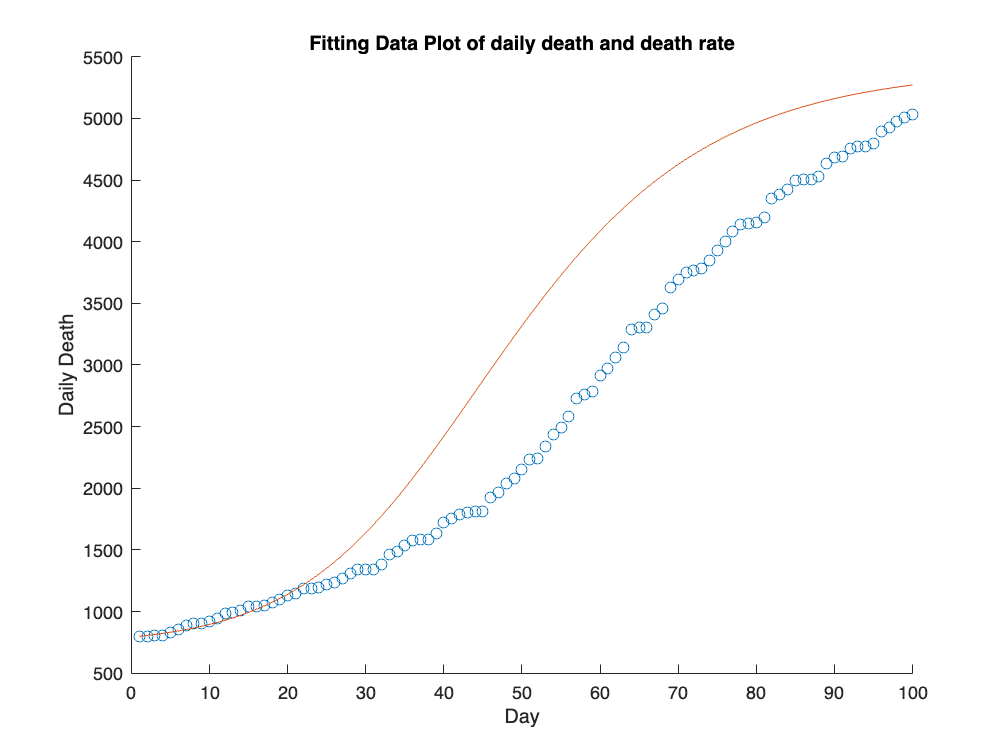

scatter(time, daily_death)
hold on;
plot(time, y(:,4))
xlabel('Day')
ylabel('Daily Death')
title('Fitting Data Plot of daily death and death rate')
hold off;

4)

% fitting error for daily new cases
fitting_err = [];
I = y(:,2);
for i = 1:length(daily_new_case)
    err = abs(I(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 9.7860e+04

% fitting error for daily death
fitting_err = [];
D = y(:,4);
for i = 1:length(daily_new_case)
    err = abs(D(i) - daily_new_case(i));
    fitting_err = [fitting_err, err];
end
sum(fitting_err)

ans = 1.8966e+05

## Task 7

**In the SIR model, there are three groups, which are suspectible group, infecious group and recovery group. SIR model enable us to see the trend of three groups directily like the peak of outbreak and when the outbreak decreases effects. From the simulation, we can see the impact of recovery probability and infectious probability to the spread process. We can chage **$\beta$** and **$\gamma$** to see different circumanstance, like high recovery probability can make the population of infectious decrease significantly, which can assist the policy in the real world. However, there are some limitations in SIR model, it does not consider the incubation period, which means people who already get sick does not show and distinguish as people in susceptible group. Also, SIR model does not consider the contact of people, which means that people in the public place may increase the infecious probability. In addition, SIR model does not consider the medical resources, in the simulation, the infectious people can get treatment immediately, however, people in the real world may not get treatment since the limitation of medical resources and lead death.**

## Reference

**ChatGPT**

**https://www.math.umd.edu/~rvbalan/TEACHING/MATH420Spring2023/LECTURES/Epi02_SIR.pdf**

## Acknowledge

**Jiaen Qi, Chun-Jen Chen, Jingjin Wu, Mingxing Wu**

## In-Script Funciton

function dydt = simple_SIR(beta, gamma, t, y)
    S = y(1);
    I = y(2);
    R = y(3);
    N = S + I + R;
    dS = -beta * (I/N) * S;
    dI = beta * (I/N) * S - gamma * I;
    dR = gamma * I;

    dydt = [dS; dI; dR];
end


function dydt = simple_SIR_2(t,y)
    S = y(1);
    I = y(2);
    R = y(3);
    N = S + I + R;
    beta = 0.3 + 0.6 * rand;
    gamma = 0.1 + 0.2 * rand;
    dS = -beta .* (I/N) .* S;
    dI = beta .* (I/N) .* S - gamma .* I;
    dR = gamma .* I;
    
    dydt = [dS; dI; dR];
end


function dydt = simple_SIRD(beta, gamma, delta, t, y)
    S = y(1);
    I = y(2);
    R = y(3);
    D = y(4);
    N = S + I + R + D;
    dS = -beta * (I/N) * S;  
    dI = beta * (I/N) * S - gamma * I;
    dR = gamma * I;
    dD = delta * I;

    dydt = [dS; dI; dR; dD];
end